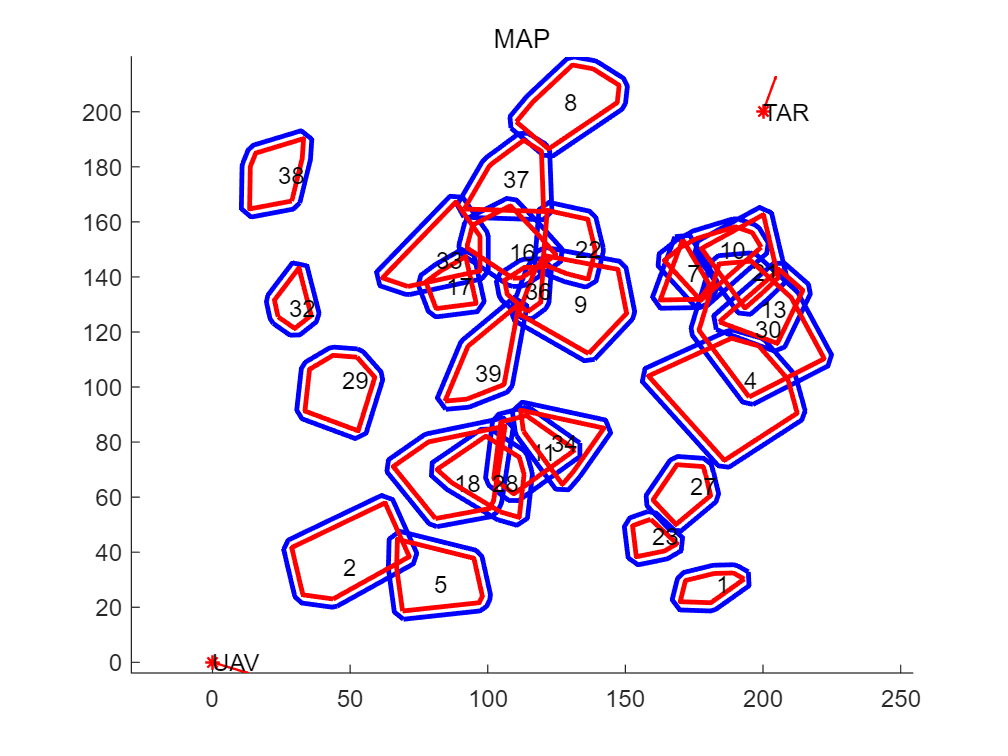

clear all
%% 定义函数输入
r=7;%最小转弯半径
Stepsize=0.01;%路径的生成间隔

sure=3;%保证安全的预留距离
% R=10+sure;


mapsize=200;
num=0;%%%%随机障碍物数量
R=[10,30];%%%障碍物半径范围;
num_obs_nocircle=40;
num_steps=100;%%%%边界上几个点
% Start_Point = [100,0,-pi/6];
% End_Point = [200,200,-pi/2];%[x,y,角度]

% Start_Point = [round(rand(1,2)*mapsize),-pi+rand(1)*2*pi];
% End_Point = [round(rand(1,2)*mapsize),-pi+rand(1)*2*pi];%[x,y,角度]

Start_Point = [0,0,-pi+rand(1)*2*pi];
End_Point = [200,200,-pi+rand(1)*2*pi];%[x,y,角度]

[outline_all,obs_no_circle,obs_no_circle_in]=obtain_obs_no_circle_all(num_obs_nocircle,mapsize,R,num_steps,Start_Point,End_Point,sure);


[obs,obs_no_circle,obs_no_circle_in,outline_all]=obtain_map(num,mapsize,Start_Point, End_Point,R,r,obs_no_circle,obs_no_circle_in,outline_all);%[x,y,障碍物的安全半径R]


r_search=15;%%探测半径
k_att=1.5;%计算引力需要的增益系数
k_rep=30;%计算斥力的增益系数，都是自己设定的。
total_field=obtian_field(mapsize+R(2)+sure,End_Point,outline_all,k_att,k_rep,r_search);

% load("0317_2.mat") 
% load('xiazhai8.mat')
figure 
Draw_map(Start_Point,End_Point,obs,sure,obs_no_circle,obs_no_circle_in);%绘制地图



tic
[final_path,open,close]=A_dubins_nocircle(Start_Point,End_Point,obs,sure,r,obs_no_circle,obs_no_circle_in,outline_all,Stepsize,total_field);

from           -1                  avoid  2
1
1.2
directly find 1-2 safe
from           -1                  avoid  9
1
1.1
directly find 1-2 safe
from           -1                  avoid  18
1
1.2
directly find 1-2 safe
from           -1                  avoid  22
1
from           -1                  avoid  39
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
from           2                  avoid  9
1
1.1
directly find 1-2 safe
from           2                  avoid  22
1
from           2                  avoid  36
1
from           2                  avoid  39
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
from           2                  avoid  9
1
1.1
directly find 1-2 safe
from           2                  avoid  22
1
from           2                  avoid  36
1
from           2                  avoid  39
1
1.1
directly find 1-2 safe
1.2
directly find 1-2 safe
open is empty!Mayday!
第一次加入mayday
from           2                  avoid  1
3
3 succed 1
directly find 

toc
figure
Draw_map(Start_Point,End_Point,obs,sure,obs_no_circle,obs_no_circle_in);%绘制地图
Draw_pathA_no_circle(final_path);
hold off
figure

Draw_map(Start_Point,End_Point,obs,sure,obs_no_circle,obs_no_circle_in);%绘制地图
Draw_pathA_no_circle_open_close(close);
Draw_pathA_no_circle_open_close(open);
hold off

[draw_path,vtheta_all]=obtain_vtheta_drawpath_nocircle(final_path);
